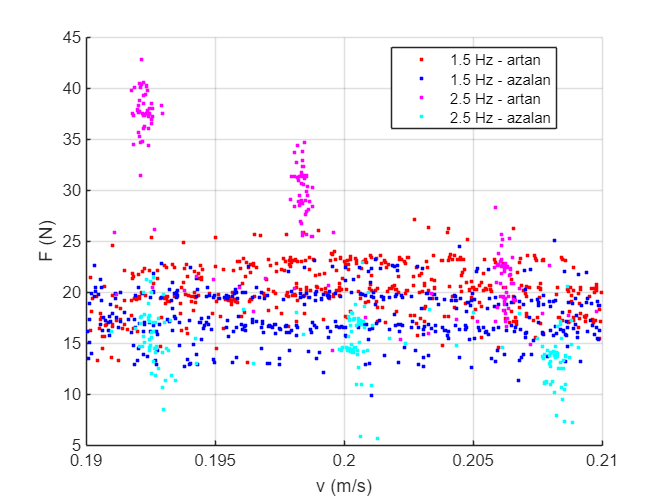

v15 = d_15.v_mPs; a15 = d_15.a_mPs2; F15 = d_15.F_friction;
v25 = d_25.v_mPs; a25 = d_25.a_mPs2; F25 = d_25.F_friction;

a_eps = 0.02*max(abs(a15));   % %2 deadband (istersen 0.01 de olur)
idx_acc15 = a15 >  a_eps;
idx_dec15 = a15 < -a_eps;


a_eps = 0.02*max(abs(a25));
idx_acc25 = a25 >  a_eps;
idx_dec25 = a25 < -a_eps;


v0 = 0.2;   % hedef hiz
dv = 0.01;  % tolerans (0.005-0.02 arasi deneyebilirsin)

idx_v15 = abs(v15 - v0) < dv;
idx_v25 = abs(v25 - v0) < dv;


figure; hold on; grid on;

plot(v15(idx_v15 & idx_acc15), F15(idx_v15 & idx_acc15), 'r.', 'DisplayName','1.5 Hz - artan');
plot(v15(idx_v15 & idx_dec15), F15(idx_v15 & idx_dec15), 'b.', 'DisplayName','1.5 Hz - azalan');

plot(v25(idx_v25 & idx_acc25), F25(idx_v25 & idx_acc25), 'm.', 'DisplayName','2.5 Hz - artan');
plot(v25(idx_v25 & idx_dec25), F25(idx_v25 & idx_dec25), 'c.', 'DisplayName','2.5 Hz - azalan');

xlabel('v (m/s)'); ylabel('F (N)');
legend('Location','best');

Facc15 = mean(F15(idx_v15 & idx_acc15))

Facc15 = 20.3131

Fdec15 = mean(F15(idx_v15 & idx_dec15))

Fdec15 = 17.6062

dF15   = Facc15 - Fdec15;

Facc25 = mean(F25(idx_v25 & idx_acc25));
Fdec25 = mean(F25(idx_v25 & idx_dec25));
dF25   = Facc25 - Fdec25;

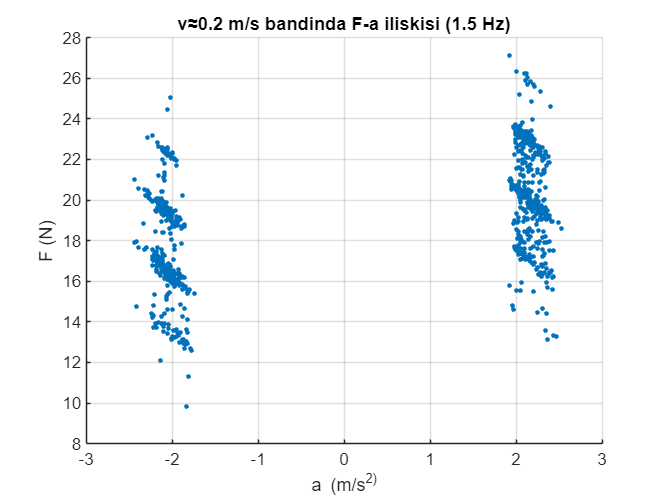

v0 = 0.2; dv = 0.01;
idx = abs(d_15.v_mPs - v0) < dv;

figure; grid on; hold on;
scatter(d_15.a_mPs2(idx), d_15.F_friction(idx), 8, 'filled');
xlabel('a (m/s^2)'); ylabel('F (N)');
title('v≈0.2 m/s bandinda F-a iliskisi (1.5 Hz)');


p = polyfit(d_15.a_mPs2(idx), d_15.F_friction(idx), 1);
slope15 = p(1)   % N / (m/s^2)

slope15 = 0.6181

inter15 = p(2)   % N

inter15 = 18.9310

v0 = 0.2; dv = 0.01;
idx25 = abs(d_25.v_mPs - v0) < dv;

p25 = polyfit(d_25.a_mPs2(idx25), d_25.F_friction(idx25), 1);
slope25 = p25(1)

slope25 = 0.9993

inter25 = p25(2)

inter25 = 21.5242


slope15 = 0.6181;  % senin bulduğun
ratio = slope25 / slope15

ratio = 1.6167

v0 = 0.2;      % m/s
dv = 0.01;

freq   = [0.5 1 1.5 2 2.5 3];
dataSet = {d_05, d_1, d_15, d_2, d_25, d_3};

slope = zeros(size(freq));
inter = zeros(size(freq));

for k = 1:length(dataSet)
    [slope(k), inter(k)] = getSlopeAtV(dataSet{k}, v0, dv);
end